This livescript aims to explore the interesting finding in the ancitipation phase (placebo-control, correlation).

intermedpath='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles'; 
load(fullfile(intermedpath,'data_frame'),'df');

% load('C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\vectorized_images_full_masked_10_percent_equalmask.mat')
load('C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\vectorized_images_full_masked_10_percent_equal.mat')


img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip\anticip_diff_r_rnd_pos_ptfce.nii.gz'

img = 'C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip\anticip_diff_r_rnd_pos_ptfce.nii.gz'


thresholdfrommaxstat=4.468%4.62; %4.7 for the placebo-control contrast and 4.62 for the correlation between brain activity and behavior contrast

thresholdfrommaxstat = 4.4680

vectorizedimg=v_masked_BK(img);

Compressed NIfTI files are not supported.


% vectorizedimg_masked=vectorizedimg(dfv_masked.both_brainmask); this was
% here but was too lazy to load in
vectorizedimg_masked=vectorizedimg(dfv_masked.anticip_brainmask);
signifmask=vectorizedimg_masked>thresholdfrommaxstat;
find(signifmask)

ans =        68687       68688       68749       68810       73235       73296       73297       73298       73299       73359       73360       73361       73421       73422


sum(signifmask)

ans = 14

studyrank=10

studyrank = 10

% subjmean(dfv_masked.anticip_placebo{studyrank,1}(:,signifmask))-
subjmean(dfv_masked.anticip_control{studyrank,1}(:,signifmask))

ans =     5.4219
   -3.6072
   -8.5867
    1.8565
   -4.2213
   -2.8418
   -1.7542
    1.1658
   -7.4858
    3.6119


%correlation analysis only makes sense in within-subject studies.
for studyrank=1:height(df)
    if ~isempty(dfv_masked.anticip_placebo{studyrank,1}) && strcmp(df.study_design{studyrank},'within') && ~df.contrast_imgs_only(studyrank)
%         df.putamensctivation{studyrank}=subjmean(dfv_masked.anticip_placebo{studyrank,1}(:,signifmask))-subjmean(dfv_masked.anticip_control{studyrank,1}(:,signifmask));
        df.putamensctivation{studyrank}=mean(dfv_masked.anticip_placebo{studyrank,1}(:,signifmask)-dfv_masked.anticip_control{studyrank,1}(:,signifmask),2,'omitnan');
    elseif isempty(dfv_masked.anticip_placebo{studyrank,1}) && strcmp(df.study_design{studyrank},'within') && df.contrast_imgs_only(studyrank) && df.anticipismodeled(studyrank)
%         df.putamensctivation{studyrank}=subjmean(dfv_masked.anticip_placebo_minus_control{studyrank,1}(:,signifmask));
        df.putamensctivation{studyrank}=mean(dfv_masked.anticip_placebo_minus_control{studyrank,1}(:,signifmask),2,'omitnan');
    end
end
% activity.painplac(counter)=subjmean(dfv_masked.pain_placebo{studyrank,1}(:,signifmask));
% activity.paincontr(counter)=subjmean(dfv_masked.pain_control{studyrank,1}(:,signifmask));
%save(fullfile(intermedpath,'data_frame.mat'), 'df');


activity=[];
counter=1;
for studyrank=1:height(df)
    if ~isempty(dfv_masked.anticip_placebo{studyrank,1})
        activity.antplac(counter)=avgnormalize(dfv_masked.anticip_placebo{studyrank,1}(:,signifmask));
        activity.antcontr(counter)=avgnormalize(dfv_masked.anticip_control{studyrank,1}(:,signifmask));
        activity.painplac(counter)=avgnormalize(dfv_masked.pain_placebo{studyrank,1}(:,signifmask));
        activity.paincontr(counter)=avgnormalize(dfv_masked.pain_control{studyrank,1}(:,signifmask));
        activity.studynm(counter)=df.study_ID(studyrank);
        counter=counter+1;
    end


end
%todo use the code snippet below to find clusters in the data, first one
%need to get rid off the Na values(see also the script for visualization)
% minSeparation = 200;
% nonZeroElements = ~bwareaopen(~dfv_masked.anticip_brainmask3d, minSeparation);
% [labeledRegions, numRegions] = bwlabel(nonZeroElements);

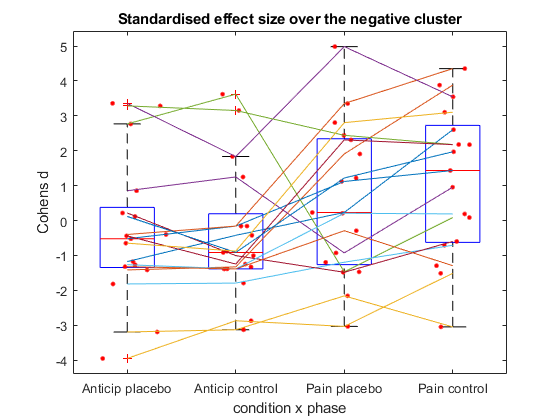

data = [activity.antplac', activity.antcontr',  activity.painplac',activity.paincontr'];
figure()
% Create a boxplot
boxplot(data, 'Labels', {'Anticip placebo',  'Anticip control', 'Pain placebo','Pain control'});
title('Standardised effect size over the negative cluster');
xlabel('condition x phase');
ylabel('Cohens d');
hold on;  % Allow multiple plots on the same axes

% Plot individual data points as an overlay
numGroups = size(data, 2);
for i = 1:numGroups
    x = i + randn(size(data, 1), 1) * 0.1;  % Add jitter for visibility
    plot(x, data(:, i), 'r.', 'MarkerSize', 10);
end
numGroups = size(data, 1);
colors = colormap(lines(numGroups));
for i = 1:size(data, 1)
    lineColors = colors(i, :);
    plot([1, 2, 3 ,4], [data(i, 1), data(i, 2),data(i, 3),data(i, 4)], '-','Color', lineColors);  % Connect Group 1 and Group 2
end


hold off

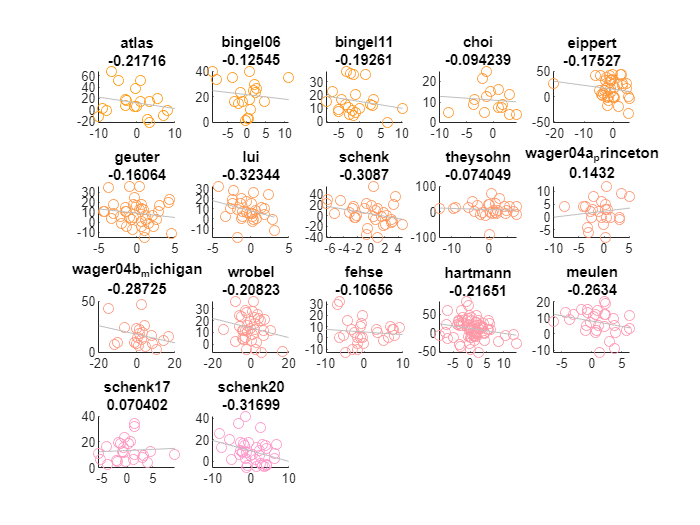

%correlation between mean cluster value and ratings
i=1;
for studyrank=1:height(df) %stats
    
    if ~isempty(df.putamensctivation{studyrank,1}) 
        h(i)=subplot(4,5,i);
        %IMPORTANT here the sign of the behavior variable is flipped as in
        %the wholebrain paper
        RGB = [255 153 i*12]/256;
        
        ratings=df.GIV_stats_rating101(studyrank).delta; %this is placebo-control delta, as it was the order in the summary_within arguments in the A_meta_analysis_placebo_all_BK script. 
        ratings=-ratings; %ratings originally show placebo-control(see previous row comment), and now we change so higher values mean higher placebo analgesia
%         ratingsnormalized=(ratings-mean(ratings,'omitnan'))/std(ratings,'omitnan');
        brainactivity=df.putamensctivation{studyrank,1};
%         brainacitvity=mean(dfv_masked.anticip_placebo{studyrank,1}(:,signifmask_masked)-...
%             dfv_masked.anticip_control{studyrank,1}(:,signifmask_masked),2,'omitnan');
%         brainacitvitynormalized=(brainacitvity-mean(brainacitvity,'omitnan'))/std(brainacitvity,'omitnan');

%         scatter(h(i),brainacitvitynormalized,ratingsnormalized,[],RGB)
        scatter(h(i),brainactivity,ratings,[],RGB)
%         maki=dfv_masked.anticip_placebo{studyrank,1}(:,signifmask_masked)-dfv_masked.anticip_control{studyrank,1}(:,signifmask_masked);
%         coracrossvoxels=mean(corr(maki,ratingsnormalized,'Rows','complete'));
        coracrossvoxels=mean(corr(brainactivity,ratings,'Rows','complete'));
        title(h(i),{df.study_ID{studyrank};string(coracrossvoxels)})
% 
        h(i)=lsline;

    i=i+1;
    end
    
    
end

img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\pain\pain_diff_rputact_rnd_pos_ptfce.nii.gz'

img = 'C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\pain\pain_diff_rputact_rnd_pos_ptfce.nii.gz'


thresholdfrommaxstat=4.59; %4.7 for the placebo-control contrast and 4.62 for the correlation between brain activity and behavior contrast
vectorizedimg=v_masked_BK(img);

Compressed NIfTI files are not supported.


vectorizedimg_masked=vectorizedimg(dfv_masked.both_brainmask);
signifmask=vectorizedimg_masked>thresholdfrommaxstat;
sum(signifmask)

ans = 1455

%get the clusters from the image
vol = spm_vol(img);

Compressed NIfTI files are not supported.


[Y,XYZ] = spm_read_vols(vol);

dim = size(Y);
[R,C,P] = ndgrid(1:dim(1),1:dim(2),1:dim(3));
ind = Y > 4.59;
Y = Y(ind);
RCP = [R(:)';C(:)';P(:)'];
XYZ = XYZ(:,ind);
RCP = RCP(:,ind);
[N,Z,M,A,maki] =spm_max(Y(:),RCP)

N =            8
           8
          14
        1087
          14
           1
        1087
           2
        1087
        1087


Z =     4.7191
    4.5960
    4.7076
    4.6440
    4.6460
    4.6277
    4.7729
    4.6280
    5.1707
    5.0650


M =     42    44    42    38    44    66    27    65    29    29    52    38    37    59    49    61    52    37    37    52    54    33    60    52    53    33    36    37    54    49    54    36    41    56    51    49    54    51    44    55    45    44    45    47    43    48    67    55    62    66
    41    39    37    38    38    37    43    34    41    44    33    44    46    30    31    33    35    45    46    49    26    33    34    35    35    38    38    38    49    30    30    32    48    51    62    30    30    62    32    34    29    32    32    20    34    20    70    62    64    57
    15    17    20    20    20    21    21    23    23    23    24    24    24    25    25    25    25    25    25    25    26    26    26    26    26    26    26    26    26    27    27    27    27    27    27    28    28    28    29    29    30    30    30    31    31    32    41    46    46    61


A =      1
     1
     2
     3
     2
     4
     3
     5
     3
     3


maki = 1×18 cell array
    {3×8 double}    {3×14 double}    {3×1087 double}    {3×1 double}    {3×2 double}    {3×1 double}    {3×3 double}    {3×65 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×4 double}    {3×2 double}    {3×8 double}    {3×47 double}    {3×4 double}    {3×4 double}    {3×202 double}


function meancohend=avgnormalize(data)
    meancohend=mean(mean(data,2,'omitnan')./std(data,0,2,'omitnan'),'omitnan');
end
function subjmean=subjmean(data)
    subjmean=mean(data,2,'omitnan')./std(data,0,2,'omitnan');
end
